% First generate a random 10x10 matrix A and a random RHS column vector b 
% You should use the command X=rand(M,N), where M is the number of rows and N is the number of columns in the array
%
A = rand(10,10);
b = rand(10,1);

% Now solve the linear system using \ to find the solution x
%
x=A\b;
x
%
% You can check for yourself that this does indeed solve the system by calculating A*x and comparing it to b.

% Form matrix A
A = [
    1,1,1;
    2,4,2.5;
    1,0,-6
];

% Form vector b
b = [
    950;
    2450;
    0
];

% Compute vector x
x = A\b;

% Extract number of adults
nAdult = x(2);
x

z = zeros(5,5);
[eye(10) [z;z];z,z,z]

A = rand(15,15);
% Now create a new variable v which is a column vector
% made from the main diagonal of A using the diag() function
v = diag(A)

% First create a random 15x15 matrix A using the rand() command
A = rand(15,15);
% Now create a new variable v which is a column vector
% made from the main diagonal of A using the diag() function
v = diag(A);
% Now create a 10x10 diagonal matrix D made from the first ten elements of v. 
% Think carefully about the easiest way to do this. Remember you can create as many new variables as you want

D = diag(v(1:10))

v = [1;2;3;4];

%Create a matrix A with the entries of v on the 3rd super diagonal.
A = diag(v,3)
B = diag(v, -1)

n=10;
A = gallery('tridiag',n,1,2,4)

n=10;
A = full(gallery('tridiag',n,1,2,4))

% Create a 5x5 tridiagonal matrix A with entries 1, 2, 4 as a sparse matrix.
A = gallery('tridiag', 5, 1,2,4);

% Create a 5x5 tridiagonal matrix B with entries 1, 2, 4 as a *full* matrix.
B = full(gallery('tridiag', 5, 1,2,4))

B =      2     4     0     0     0
     1     2     4     0     0
     0     1     2     4     0
     0     0     1     2     4
     0     0     0     1     2


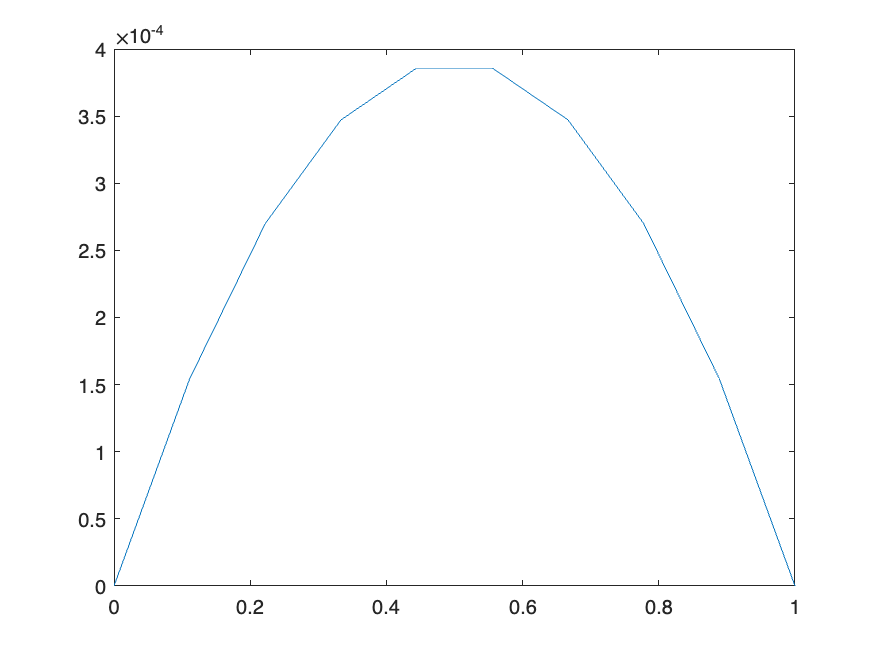

%Create a matrix corresponding to the discrete second derivative and boundary condtions
A = full(gallery('tridiag', 10, 1, -2, 1));
A(10,9)=0;
A(1,2)=0;
A(1,1)=1;
A(10,10)=1;

% Create a column vector b with 10 entries that is zero at the ends (boundary conditions) and -0.01 in every other entry.
b = ones(10,1)*-0.01;
b(1,1)=0;
b(10,1)=0;

% Create a vector u that solves Au = (Delta y)^2/E b.
u = A\b/3.2*(1/9)^2;

%Create a column vector of 10 evenly spaced points between 0 and 1 for plotting
y = linspace(0,1,10)';

%Plot  on the vertical axis, and  on the horizontal axis.
plot(y,u)